# 运动控制系统实验

sheets=sheetnames("exprData.xlsx");
ps=zeros(size(sheets));

## 开环实验与单闭环实验

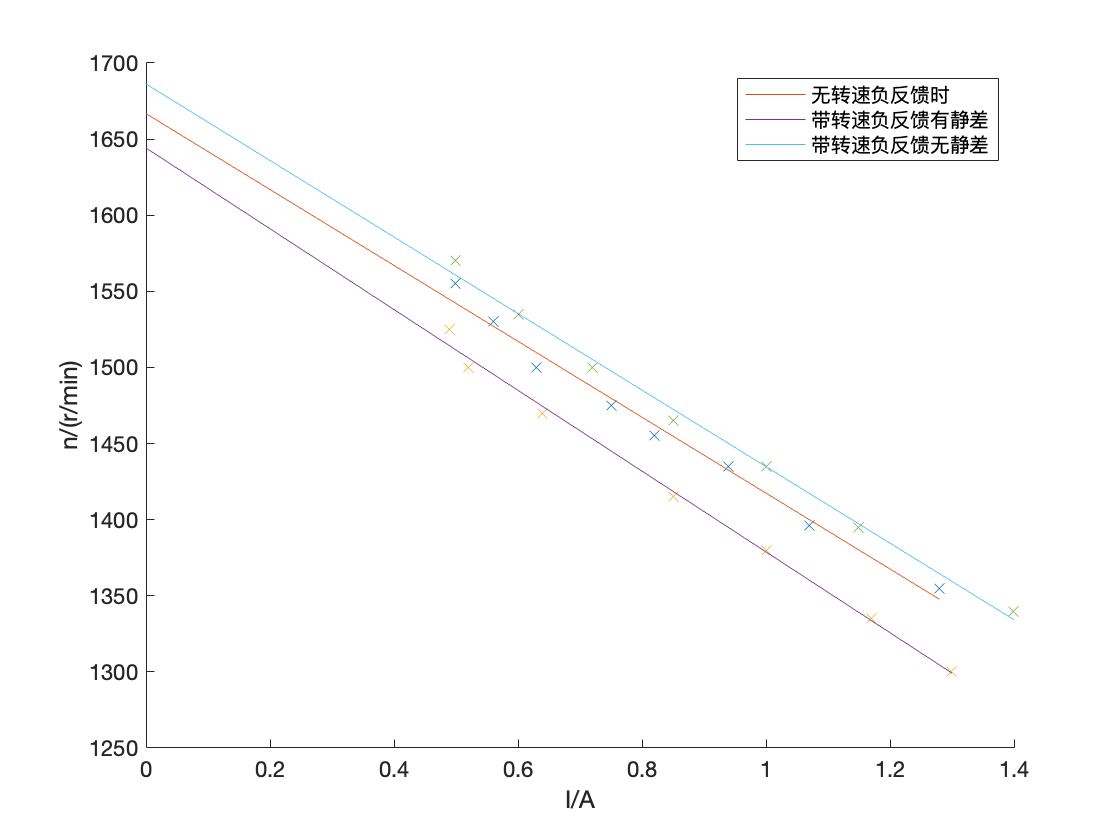

figure();
hold on;
labels={'无转速负反馈时','带转速负反馈有静差','带转速负反馈无静差'};
for i=1:3
    data=readmatrix("exprData.xlsx","Sheet",sheets(i));
    I=data(1,2:end);
    u=data(2,2:end);
    n=data(3,2:end);
    p=polyfit(I,n,1);
    x=[0,I];
    f = polyval(p,x); 
    plot(I,n,'x');
    ps(i)=plot(x,f,'-');
end
xlabel('I/A');
ylabel('n/(r/min)');
legend(ps(1:3),labels)

## 双闭环实验

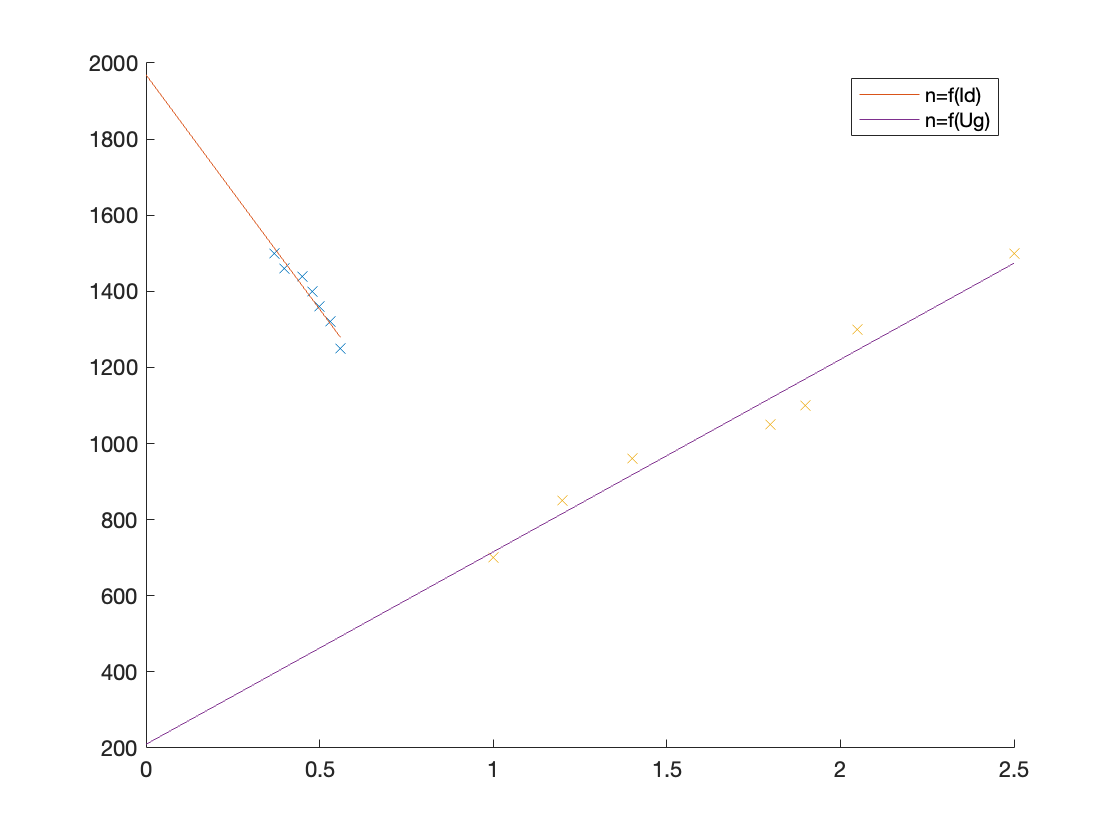

figure();
hold on;
for i=4:5
    data=readmatrix("exprData.xlsx","Sheet",sheets(i));
    n=data(1,2:end);
    I=data(2,2:end);
    p=polyfit(I,n,1);
    x=[0,I];
    f = polyval(p,x); 
    plot(I,n,'x');
    ps(i)=plot(x,f,'-');
end
labels={'n=f(Id)','n=f(Ug)'};
legend(ps(4:5),labels)